# Exercise 2

https://nl.mathworks.com/help/images/reduce-the-number-of-colors-in-an-image.html?s_tid=srchtitle

## Reducing colour with color approximation

### Reducing colours with Unifrom quantization

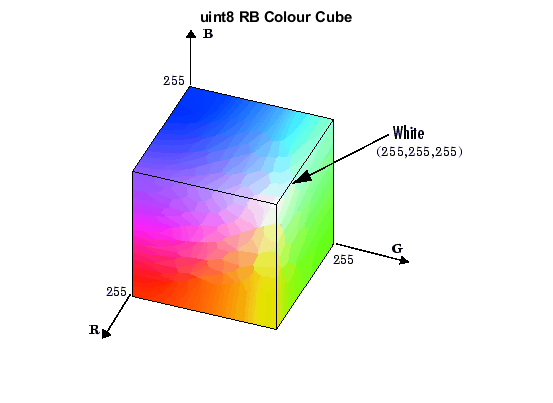

imshow('colorcube.gif')
title('uint8 RB Colour Cube')

This method work by quantization of the colour cube

When taking a slice of the the colour cube we see that we can quantize the plane in squares (in reality cubes)

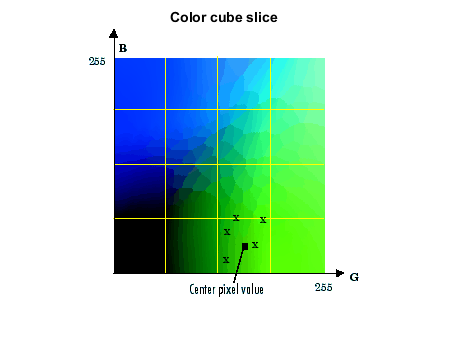

imshow("colorCubePlane.gif")
title("Color cube slice")

When using rgb2ind we can give a tollerance wich will indicate how large the cubes are inside the colourcubes. 

if tolerance is 0.1 then the cubes will have an edge length of 1/10 the length of the RGB cube

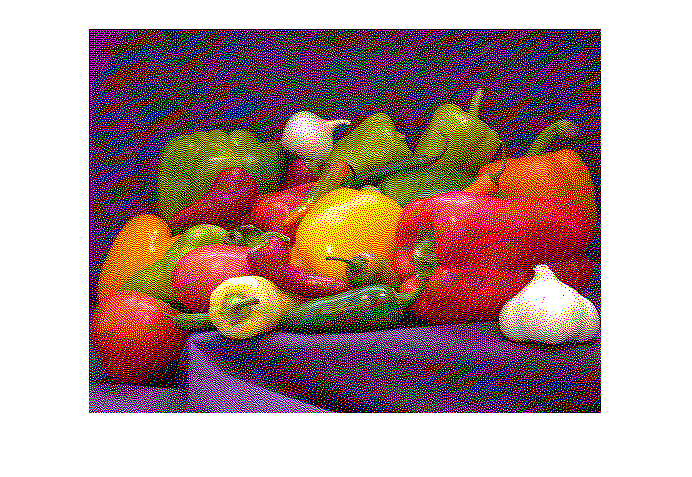

RGB = imread('peppers.png');
[x,map] = rgb2ind(RGB, 0.9);
imshow(x, map)

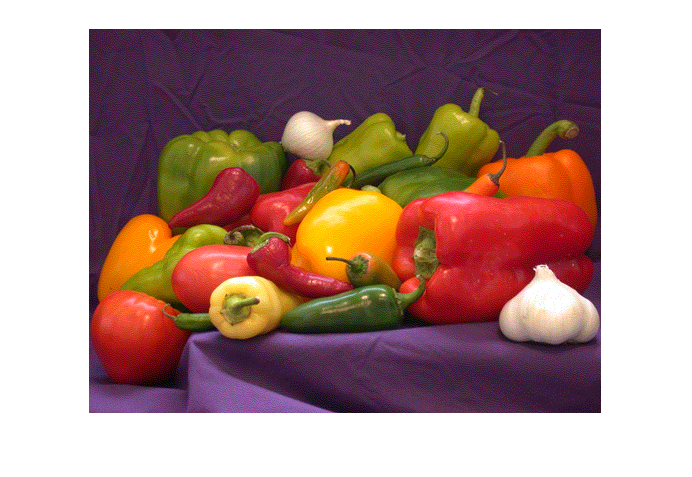


RGB2 = imread('peppers.png');
[x,map] = rgb2ind(RGB2, 0.1);
imshow(x, map)

### Reducing color using Minimum Variance Quantization

Minimum Variance quantization work by associating pixels into groups based on what the variance is between the values of the pixels. The shapes can now differ in size. You can give a number that will determine how many boxes their will, also resulting in how many colours ther will be.

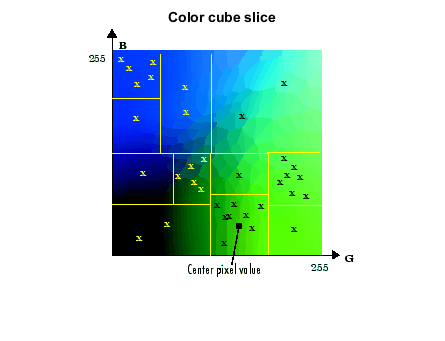

imshow("ColorCubeVariance.gif");
title("Color cube slice")

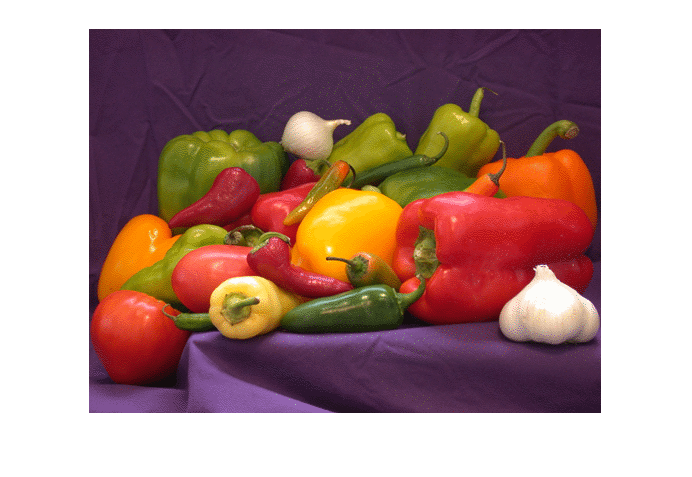


RGB = imread('peppers.png');
[X,map] = rgb2ind(RGB,185);
imshow(X,map)

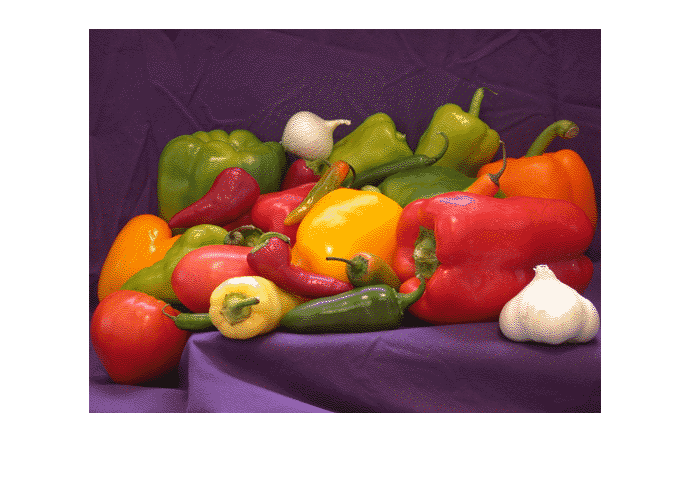


RGB = imread('peppers.png');
[X,map] = rgb2ind(RGB,52);
imshow(X,map)

## Reducing colors of indexed image using imapprox

De imapprox function reduces the number of colors in an indexed image. It will use the function ind2rgb to get an RGB image, followed by rgb2ind to return a new indexed image with less colours.

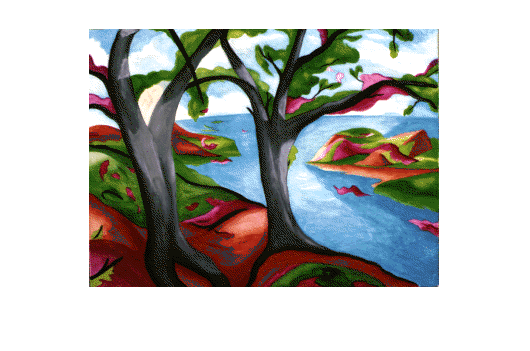

load trees
[Y,newmap] = imapprox(X,map,128);
imshow(Y,newmap)

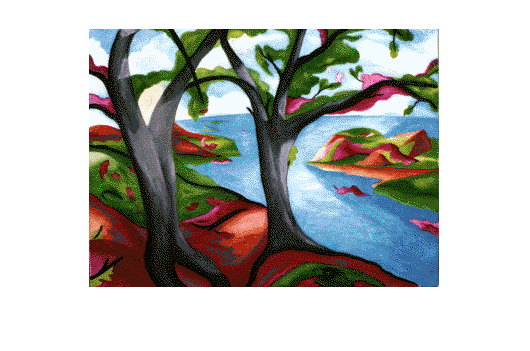


load trees
[Y,newmap] = imapprox(X,map,64);
imshow(Y,newmap)

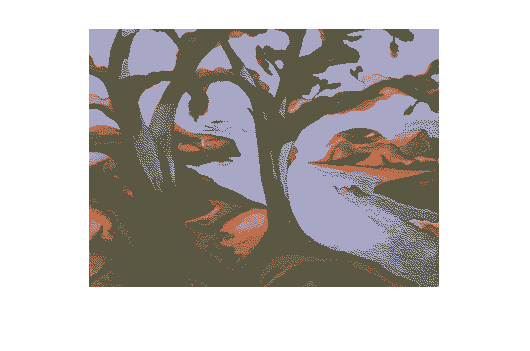


load trees
[Y,newmap] = imapprox(X,map,3);
imshow(Y,newmap)

## Dithering

rgb2ind and imapprox preform dithering. If you just would reduce the colours, then the images might not look that nice.  This is why the functions use dithering.

Dithering makes it look that their are a more number of colors than there are. This is by chaning the the colors of pixels in a neighbourhood so that the everage color of the neihbour looks like the original RBB value.

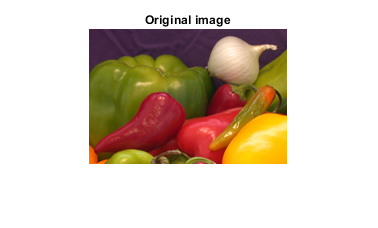

rgb = imread('onion.png'); 
imshow(rgb)
title('Original image')

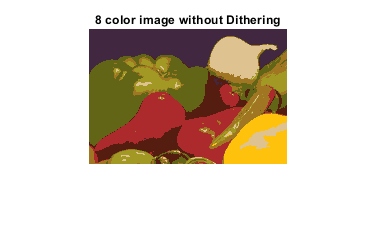


[X_no_dither,map] = rgb2ind(rgb,8,'nodither');
imshow(X_no_dither,map)
title('8 color image without Dithering')

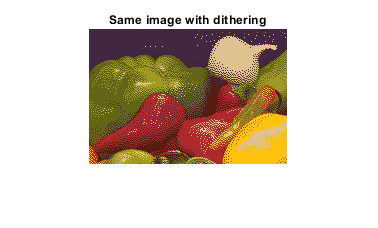


[X_dither,map] = rgb2ind(rgb,8,'dither');
imshow(X_dither,map)
title('Same image with dithering')